# Illustrate Poisson Distribution of Electrons

The Poisson nature of the sensor absorptions, for a noise-free camera.

We create a uniform scene with a small field of view.  We then image this onto the center of a small sensor (monochrome).  We plot the number of electrons for different exposure durations.

In the last section, we turn on the sensor noise.  This illustrates the relative size of the Photon noise and Sensor noise for this particular case.

%% Fire up ISET
ieInit

%% Build the scene, oi, and sensor.  Could use camera here!
scene = sceneCreate('uniform');
scene = sceneSet(scene,'fov',2);    % Small field of view
oi = oiCreate;
oi = oiCompute(oi,scene);

% Build a sensor
sensor = sensorCreate('monochrome');
sensor = sensorSetSizeToFOV(sensor,1.5);
sensor = sensorSet(sensor,'noise flag',1);  % Only photon noise

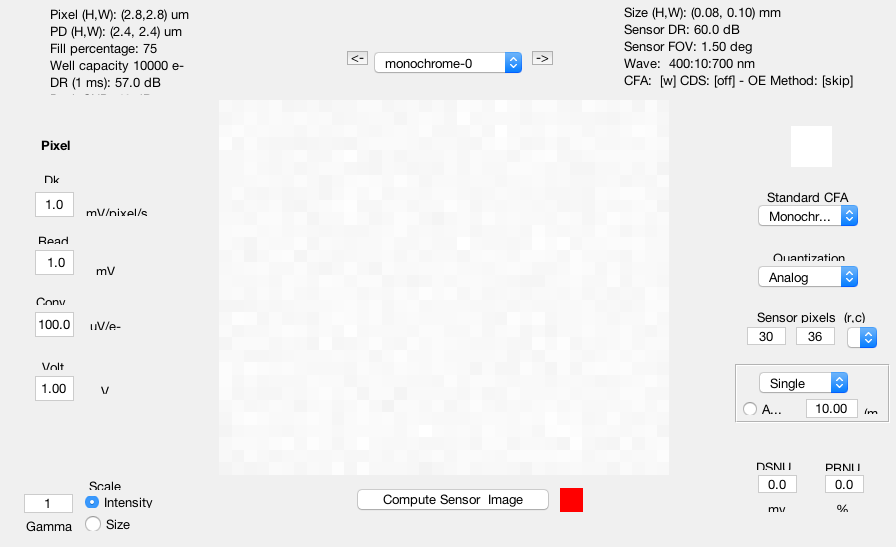

% Calculate response using relatively long exposure
longE = 1e-2;
sensor = sensorSet(sensor,'exp time',longE); 
sensor = sensorCompute(sensor,oi);
ieAddObject(sensor); sensorWindow('scale',1);

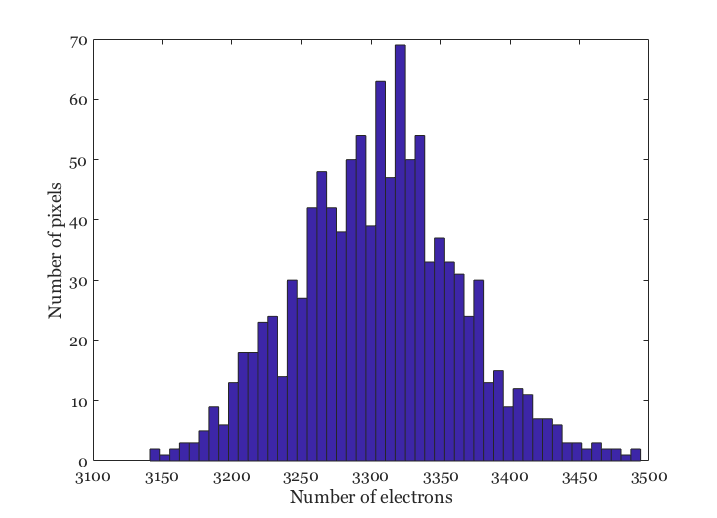


% Plot the distribution of absorptions
vcNewGraphWin;
e = sensorGet(sensor,'electrons');
hist(e(:),50);
xlabel('Number of electrons');
ylabel('Number of pixels');

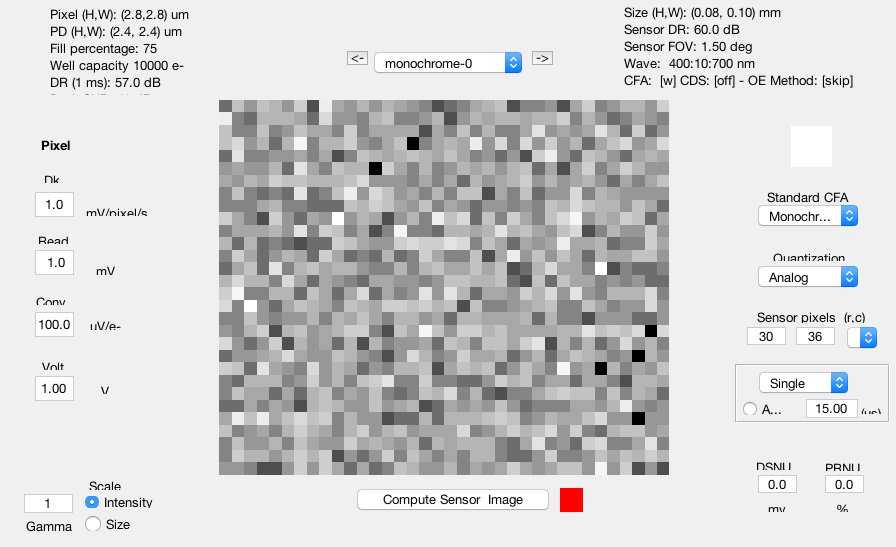

% Shorten the exposure duration by 1000 and run it again
shortE = 1.5e-5;
sensor = sensorSet(sensor,'exposure time',shortE);
sensor = sensorCompute(sensor,oi);
e = sensorGet(sensor,'electrons');
ieAddObject(sensor); sensorWindow('scale',1);

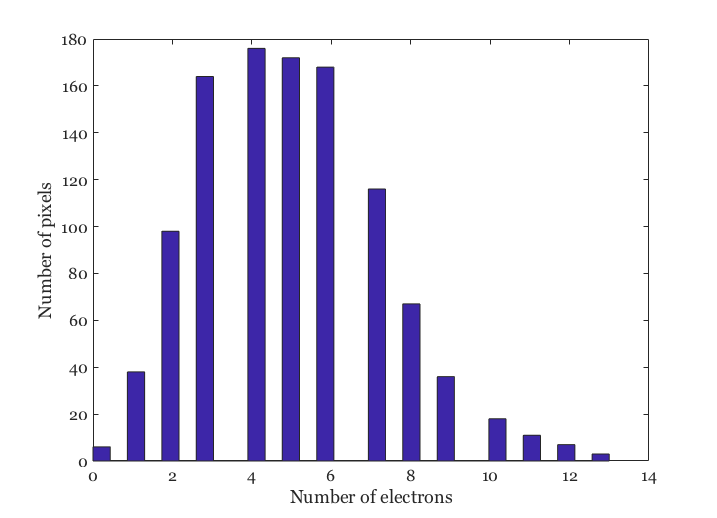


% Show the plot
vcNewGraphWin;
hist(e(:),30);
xlabel('Number of electrons');
ylabel('Number of pixels');

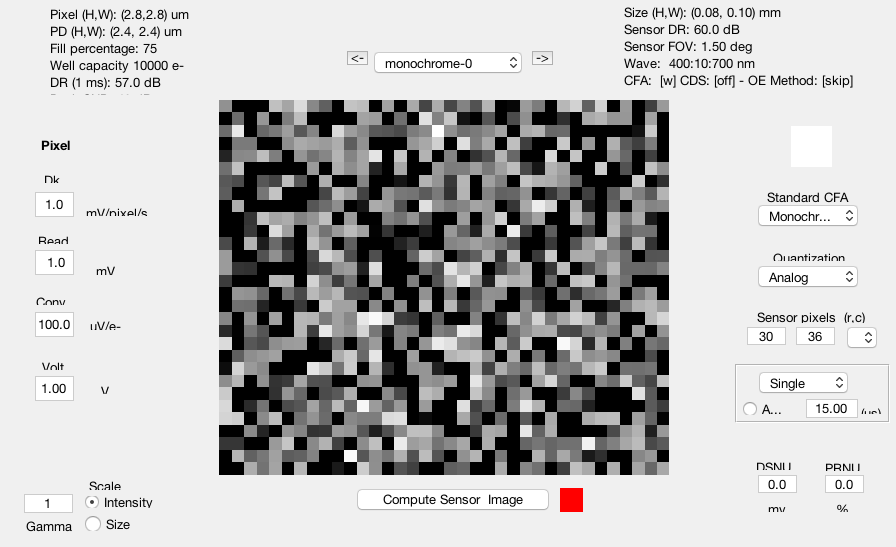

% Turn on the noise and repeat
sensor = sensorSet(sensor,'noise flag',2); 
sensor = sensorCompute(sensor,oi);
e = sensorGet(sensor,'electrons');
ieAddObject(sensor); sensorWindow('scale',1);

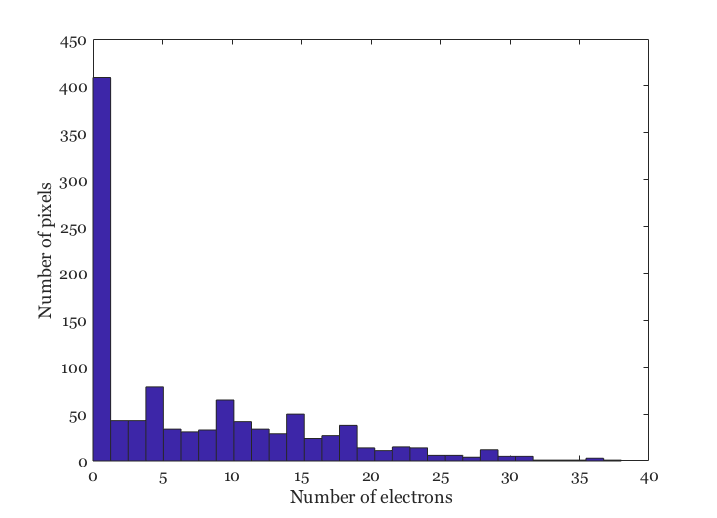


%
vcNewGraphWin;
hist(e(:),30);
xlabel('Number of electrons');
ylabel('Number of pixels');